MO=[
   24.434   0.806 
   21.648   0.851 
   21.647   0.851 
   19.094   0.871 
   19.093   0.871 
   19.093   0.871 
   17.259   0.890 
   15.567   0.893 
   15.100   0.900 
   15.100   0.900 
   15.099   0.900 
   13.721   0.902 
   13.720   0.902 
   13.720   0.902 
   13.359   0.906 
   13.358   0.906 
   13.358   0.906 
   11.329   0.908 
   11.327   0.908 
   11.289   0.908 
   11.289   0.908 
   11.289   0.908 
    9.910   0.912 
    9.910   0.912 
    9.909   0.912];

diff_e =[];

for ii =1:length(MO)-1
    allowed_e = [MO(1:ii-1,1); MO(ii+1:end,1)];
    diff_e = [diff_e; MO(ii,1) + allowed_e ];
end

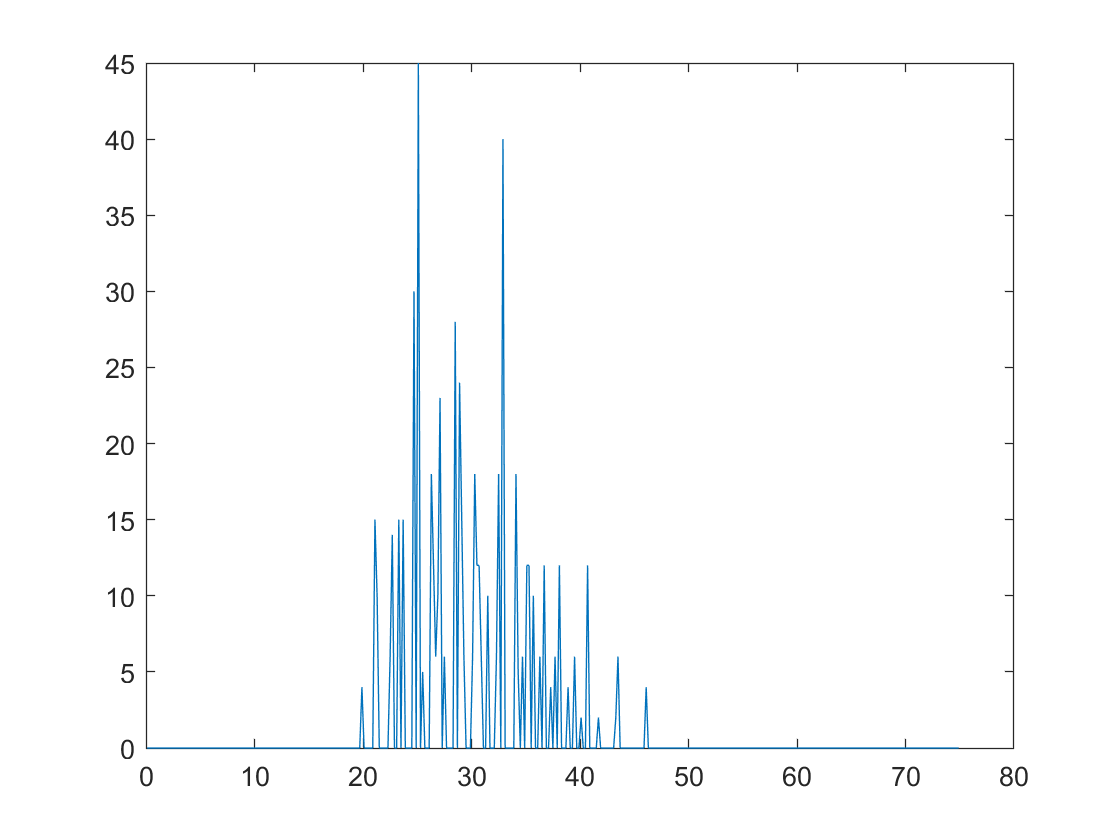

C1s = 289.5;
ke =C1s - diff_e;
binsize = 0.2;
figure
edges = 0:binsize:75;
centres = edges(1:end-1)+ diff(edges)/2;
[ke_hist,edges] = histcounts(diff_e,edges);
plot(centres,ke_hist)%,'DisplayName','ES:no RND filter')


CH = 287.1;
ke2 = C1s - CH - MO(:,1);